# Kuka LBR Robot Forward Kinematics

* Robert Garrone*

*    Worcester Polytechnic Institute, regarrone@wpi.edu*

## Introduction:

    Our task for this group assignment was to derive the forward kinematics for the KUKA LBR Robot. Since we were not given the clear directions on which LBR robot to choose we decided to use the iiwa R800 Robot. This report will walk through the methods that we used to derive the forward kinematics as well as depicts the transformations matrices for each and every link of the robot. 

### Approach:

The approach is to first read through the sources identified in the first group meeting and use the information provided in those sources to come up with the DH parameters for the Kuka LBR Robot. 

## Materials and Methods:

The following approach is used in order to solve for T-matrix for each link and T-matrix from base to the end-effector:

- Study the technical brochure for the KUKA LBR IISY model and extract model along with link distance.

- Derive DH-Table for this model

- Calculate A transformation matrices from link to link

- Calculate T matrices for each link and from base to end-effector

First we use the brochutre for the KUKA LBR IISY and extract the following information regarding the working envelope of the robotic arm:

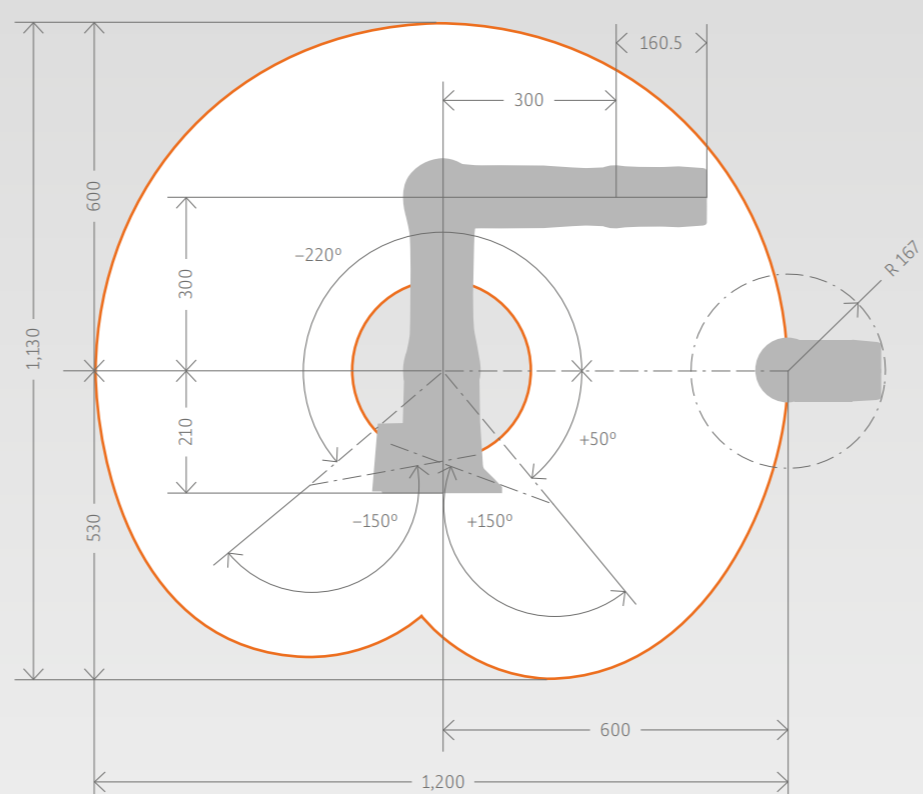

From the image above, we now know this is a 7-DoF robotic arm comprised of revolute joints. We can also see there are only four links with a translation in the z-axis:

- Base to link-1($d_{\textrm{bs}}$): 210 mm

- Link-1 to Link-2($d_{\textrm{se}}$): 300 mm

- Link-2 to Link-3($d_{\textrm{ew}}$): 300 mm

- Link-3 to Link-4($d_{\textrm{wf}}$): 160.5 mm 

Now that we know we have seven links to work with, we can go ahead and derive the DH-table that will account for all the parameters of this model ($a,\;\alpha$, d, $\left.\theta \right)\;$


$$\left\lbrack \begin{array}{ccccc}
i & a & \alpha  & d & \theta \\
1 & 0 & \frac{\pi }{2} & d_{\textrm{bs}}  & \theta_1 \\
2 & 0 & \frac{\pi }{2} & 0 & \theta_2 \\
3 & 0 & \frac{\pi }{2} & d_{\textrm{se}}  & \theta_3 \\
4 & 0 & \frac{\pi }{2} & 0 & \theta_4 \\
5 & 0 & \frac{\pi }{2} & d_{\textrm{ew}}  & \theta_5 \\
6 & 0 & \frac{\pi }{2} & 0 & \theta_6 \\
7 & 0 & 0 & d_{\textrm{wf}}  & \theta_7 
\end{array}\right\rbrack$$


From the DH-table we can draw the following statements for each link:

- Link-1: no translation in the x-axis, rotation in the x-axis, translation in the z-axis, rotation in the z-axis

- Link-2: no translation in the x-axis, rotation in the x-axis, no translation in the z-axis, rotation in the z-axis

- Link-3: no translation in the x-axis, rotation in the x-axis, translation in the z-axis, rotation in the z-axis

- Link-4: no translation in the x-axis, rotation in the x-axis, no translation in the z-axis, rotation in the z-axis

- Link-5: no translation in the x-axis, rotation in the x-axis, translation in the z-axis, rotation in the z-axis

- Link-6: no translation in the x-axis, rotation in the x-axis, no translation in the z-axis, rotation in the z-axis

- Link-7: no translation in the x-axis, rotation in the x-axis, translation in the z-axis, rotation in the z-axis

We now can calculate A-transformation matrix for each link in matlab by defining our DH table as a matrix, and then passing each row of the DH table to a function `create_DH_matrix` which calculates the DH matrix for each link. The folowing equations also describe how to calculate A matrices from the text book resulting $A_{01}$, $A_{12}$, $A_{23}$, $A_{34}$, $A_{45}$, $A_{56}$ & $A_{67}$:

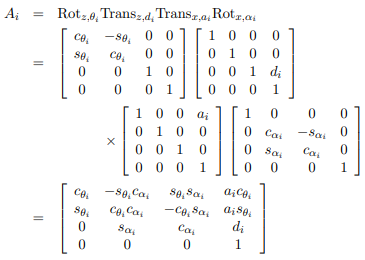

Lastly, we can calculate for the T matrices by using the A matrices found for each link. 

- $T_{01}$= $A_{01}$

- $T_{02}$= $A_{01}$*$A_{12}$

- $T_{03}$= $A_{01}$*$A_{12}$*$A_{23}$

- $T_{04}$= $A_{01}$*$A_{12}$*$A_{23}$*$A_{34}$

- $T_{05}$= $A_{01}$*$A_{12}$*$A_{23}$*$A_{34}$*$A_{45}$

- $T_{06}$= $A_{01}$*$A_{12}$*$A_{23}$*$A_{34}$*$A_{45}$*$A_{56}$

- $T_{07}$= $A_{01}$*$A_{12}$*$A_{23}$*$A_{34}$*$A_{45}$*$A_{56}$*$A_{67}$

## Results:    

Faria et al. Gives a convenient DH convention diagram of the Kuka LBR robot. It is reproduced below with each link length clearly indicated.

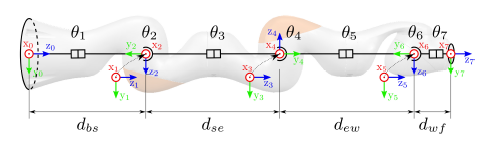

A DH table is also provided by Faria et al. for the Kuka LBR and is reproduced below:

 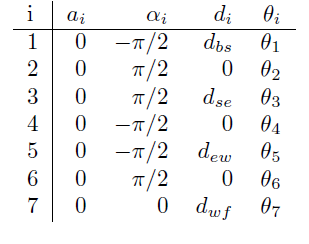

Given the DH diagram for the manipulator as well as the DH table for the manipulator, we can use MATLAB to compute the successive $A_j^i$ frame-to-frame transforms and ultimately obtain the $T_n^0$ transforms that can be used to express each link's coordinate frame in terms of the base frame.

%from Faria et al.

syms 'a%d' 'alpha%d' 'theta%d' [1 7]
syms 'd_bs' 'd_se' 'd_ew' 'd_wf'

%Create DH Table
dh_table = [
    0 -pi/2 d_bs theta1;
    0  pi/2 0    theta2;
    0  pi/2 d_se theta3;
    0 -pi/2 0    theta4;
    0 -pi/2 d_ew theta5;
    0  pi/2 0    theta6;
    0  0    d_wf theta7;]

$$dh\_table = \left(\begin{array}{cccc} 0 & -\frac{\pi }{2} & d_{\mathrm{bs}} & \theta_{1}\\ 0 & \frac{\pi }{2} & 0 & \theta_{2}\\ 0 & \frac{\pi }{2} & d_{\mathrm{se}} & \theta_{3}\\ 0 & -\frac{\pi }{2} & 0 & \theta_{4}\\ 0 & -\frac{\pi }{2} & d_{\mathrm{ew}} & \theta_{5}\\ 0 & \frac{\pi }{2} & 0 & \theta_{6}\\ 0 & 0 & d_{\mathrm{wf}} & \theta_{7} \end{array}\right)$$


%dims in meters from
%Kuka LBR iiwa7 R800 brochure
d_bs= 0.340 %base to shoulder

d_bs = 0.3400

d_se= 0.400 %shouled to elbow 

d_se = 0.4000

d_ew= 0.400 %elbow to wrist

d_ew = 0.4000

d_wf= 0.126 %wrist to to end effector

d_wf = 0.1260


%dh table w/ link lengths added.
dh_table = subs(dh_table)

$$dh\_table = \left(\begin{array}{cccc} 0 & -\frac{\pi }{2} & \frac{17}{50} & \theta_{1}\\ 0 & \frac{\pi }{2} & 0 & \theta_{2}\\ 0 & \frac{\pi }{2} & \frac{2}{5} & \theta_{3}\\ 0 & -\frac{\pi }{2} & 0 & \theta_{4}\\ 0 & -\frac{\pi }{2} & \frac{2}{5} & \theta_{5}\\ 0 & \frac{\pi }{2} & 0 & \theta_{6}\\ 0 & 0 & \frac{63}{500} & \theta_{7} \end{array}\right)$$

Above we input the DH table in Faria et al. As `dh_table` and substitute in values for the link lengths based on the brochure for the Kuka LBR iiwa7 robot.

While there exists a predefined function to obtain the successive frame transforms, we calculate each successive frame transform by passing each row of the DH table to a function `create_DH_matrix` which calculates the DH matrix. These calculations are stored as variables `A01, A12, etc` and represent the$A_j^i$ frame-to-frame transforms

%Brute Force define of the successive frame A transformations
A01 = create_dh_matrix(dh_table(1,1),dh_table(1,2), dh_table(1,3), dh_table(1,4))

$$A01 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & 0 & -\sin\left(\theta_{1}\right) & 0\\ \sin\left(\theta_{1}\right) & 0 & \cos\left(\theta_{1}\right) & 0\\ 0 & -1 & 0 & \frac{17}{50}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A12 = create_dh_matrix(dh_table(2,1),dh_table(2,2), dh_table(2,3), dh_table(2,4))

$$A12 = \left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & 0 & \sin\left(\theta_{2}\right) & 0\\ \sin\left(\theta_{2}\right) & 0 & -\cos\left(\theta_{2}\right) & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A23 = create_dh_matrix(dh_table(3,1),dh_table(3,2), dh_table(3,3), dh_table(3,4))

$$A23 = \left(\begin{array}{cccc} \cos\left(\theta_{3}\right) & 0 & \sin\left(\theta_{3}\right) & 0\\ \sin\left(\theta_{3}\right) & 0 & -\cos\left(\theta_{3}\right) & 0\\ 0 & 1 & 0 & \frac{2}{5}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A34 = create_dh_matrix(dh_table(4,1),dh_table(4,2), dh_table(4,3), dh_table(4,4))

$$A34 = \left(\begin{array}{cccc} \cos\left(\theta_{4}\right) & 0 & -\sin\left(\theta_{4}\right) & 0\\ \sin\left(\theta_{4}\right) & 0 & \cos\left(\theta_{4}\right) & 0\\ 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A45 = create_dh_matrix(dh_table(5,1),dh_table(5,2), dh_table(5,3), dh_table(5,4))

$$A45 = \left(\begin{array}{cccc} \cos\left(\theta_{5}\right) & 0 & -\sin\left(\theta_{5}\right) & 0\\ \sin\left(\theta_{5}\right) & 0 & \cos\left(\theta_{5}\right) & 0\\ 0 & -1 & 0 & \frac{2}{5}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A56 = create_dh_matrix(dh_table(6,1),dh_table(6,2), dh_table(6,3), dh_table(6,4))

$$A56 = \left(\begin{array}{cccc} \cos\left(\theta_{6}\right) & 0 & \sin\left(\theta_{6}\right) & 0\\ \sin\left(\theta_{6}\right) & 0 & -\cos\left(\theta_{6}\right) & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A67 = create_dh_matrix(dh_table(7,1),dh_table(7,2), dh_table(7,3), dh_table(7,4))

$$A67 = \left(\begin{array}{cccc} \cos\left(\theta_{7}\right) & -\sin\left(\theta_{7}\right) & 0 & 0\\ \sin\left(\theta_{7}\right) & \cos\left(\theta_{7}\right) & 0 & 0\\ 0 & 0 & 1 & \frac{63}{500}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

We can now postmultiply the successive $A_j^i$'s (i.e.`A01,A12,etc`) to composite homogeneous matricies that represent the transformation of the *nth* link in terms of the base frame. The transformation of the end effector coordinate frame in terms of the base frame is given by `T07` or $T_7^0$.

T01 = A01;
T02 = A01*A12;
T03 = A01*A12*A23;
T04 = A01*A12*A23*A34;
T05 = A01*A12*A23*A34*A45;
T06 = A01*A12*A23*A34*A45*A56;
T07 = A01*A12*A23*A34*A45*A56*A67;

%base to frame transforms
T01 = simplify(T01)

$$T01 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & 0 & -\sin\left(\theta_{1}\right) & 0\\ \sin\left(\theta_{1}\right) & 0 & \cos\left(\theta_{1}\right) & 0\\ 0 & -1 & 0 & \frac{17}{50}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T02 = simplify(T02)

$$T02 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right) & -\sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & 0\\ \cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & \sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & 0\\ -\sin\left(\theta_{2}\right) & 0 & \cos\left(\theta_{2}\right) & \frac{17}{50}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T03 = simplify(T03)

$$T03 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right) & \cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & \cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)+\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right) & \frac{2\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{5}\\ \cos\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right) & \sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)-\cos\left(\theta_{1}\right)\,\cos\left(\theta_{3}\right) & \frac{2\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{5}\\ -\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right) & \frac{2\,\cos\left(\theta_{2}\right)}{5}+\frac{17}{50}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T04 = simplify(T04)

$$T04 = \begin{array}{l} \left(\begin{array}{cccc} \cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{4}\right)-\cos\left(\theta_{4}\right)\,\sigma_{1} & -\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)-\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right) & \sin\left(\theta_{4}\right)\,\sigma_{1}+\cos\left(\theta_{1}\right)\,\cos\left(\theta_{4}\right)\,\sin\left(\theta_{2}\right) & \frac{2\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{5}\\ \cos\left(\theta_{4}\right)\,\sigma_{2}+\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{4}\right) & \cos\left(\theta_{1}\right)\,\cos\left(\theta_{3}\right)-\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right) & \cos\left(\theta_{4}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-\sin\left(\theta_{4}\right)\,\sigma_{2} & \frac{2\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{5}\\ \cos\left(\theta_{2}\right)\,\sin\left(\theta_{4}\right)-\cos\left(\theta_{3}\right)\,\cos\left(\theta_{4}\right)\,\sin\left(\theta_{2}\right) & \sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right) & \cos\left(\theta_{2}\right)\,\cos\left(\theta_{4}\right)+\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{4}\right) & \frac{2\,\cos\left(\theta_{2}\right)}{5}+\frac{17}{50}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)-\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\\ \sigma_{2}=\cos\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right) \end{array}$$

T05 = simplify(T05)

T06 = simplify(T06)

T07 = simplify(T07) %Transform from base to end effector

## Discussion:

    As you can see we developed the DH Parameter Tables for the Kuka Robot as well as created the transformation matrices from their respective Denavit-Hartenberg Transformations of Ai. We first created the Ai for each of the links respective to the link before it. Then we multiplied them in order to get the base to frame transformations. We also obtained the base to end effector transformation as denoted by T07. If we were to plot this out with all the values for Theta 1-7 we would be able to recreate the image as shown in the Datasheet depicting the range of motion for the Kuka Robot. Overall, this assingment was a very good exercise in testing our knowledge about the forward kinematics of robots and an even better exercise in group work and managing teams.

## References:

-  Spong, M. W. (2006). *Robot Modelling and Control Mark W. Spong* (pp. 35-74) (926186803 726311037 M. W. Spong, Author). Hoboken, NJ: Wiley.

- Faria, Carlos & Ferreira, Flora & Erlhagen, Wolfram & Monteiro, Sérgio & Bicho, Estela. (2018). Position-based kinematics for 7-DoF serial manipulators with global configuration control, joint limit and singularity avoidance. Mechanism and Machine Theory. 121. 317-334. 10.1016/j.mechmachtheory.2017.10.025. 

- [Kuka LBR iiwa 7 R800 Spec Brochure](https://www.kuka.com/-/media/kuka-downloads/imported/9cb8e311bfd744b4b0eab25ca883f6d3/kuka_sensitiverobotics_lbriiwa_insert_en.pdf?rev=e035c0b1a17a402986cd9a7333cde7ee&hash=DDF40BC671FA663DCC0C314AAC7D7DFD)

## Defined Functions

function dh_matrix = create_dh_matrix(a, alpha, d, theta)
    dh_matrix = [
      cos(theta), -sin(theta)*cos(alpha), sin(theta)*sin(alpha), a*cos(theta);
      sin(theta), cos(theta)*cos(alpha), -cos(theta)*sin(alpha), a*sin(theta);
      0,          sin(alpha),           cos(alpha),             d;
      0,            0,                  0,                      1];
end